# Proyecto Final: Moviles y Gravedad

## **Algoritmos Numéricos por Computadora**

## Manuel Fernández 166496

## Bernardo Altamirano 167881

## Santiago Borobia 165323

## Introducción:

Cuando modelamos dos masas que conviven en un mismo espacio y, por lo tanto, muestran fuerzas de atracción entre ellas lo hacemos de la siguiente manera.

Primero, comencaremos con un ejemplo sencillo que sería modelar la Tierra y Luna en un mismo sistema gravitacional.

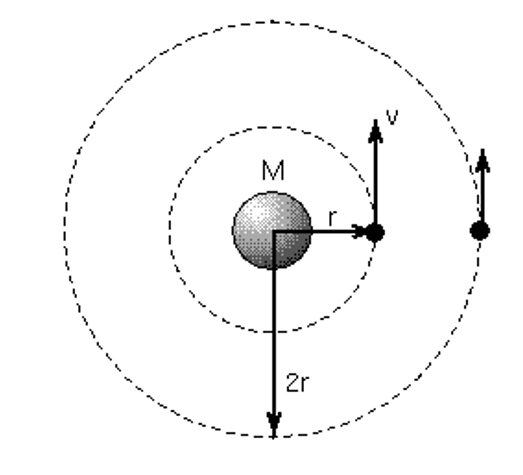

Sea M la masa de la Tierra y sea v la velocidad de un satelite (Luna) que orbita alrededor de la Tierra y, además, sea r el radio que va del centro de la Tierra al centro de la Luna (es decir, distancia de la superficie de la Tierra a la Luna más el radio de la Tierra), entonces sabemos lo siguiente:


$$M_T =\frac{{V_L }^2 r}{G}$$


Por lo tanto, si despejamos la velocidad de la Luna tenemos que:


$$V_L =\sqrt{\frac{GM_t }{r}}$$


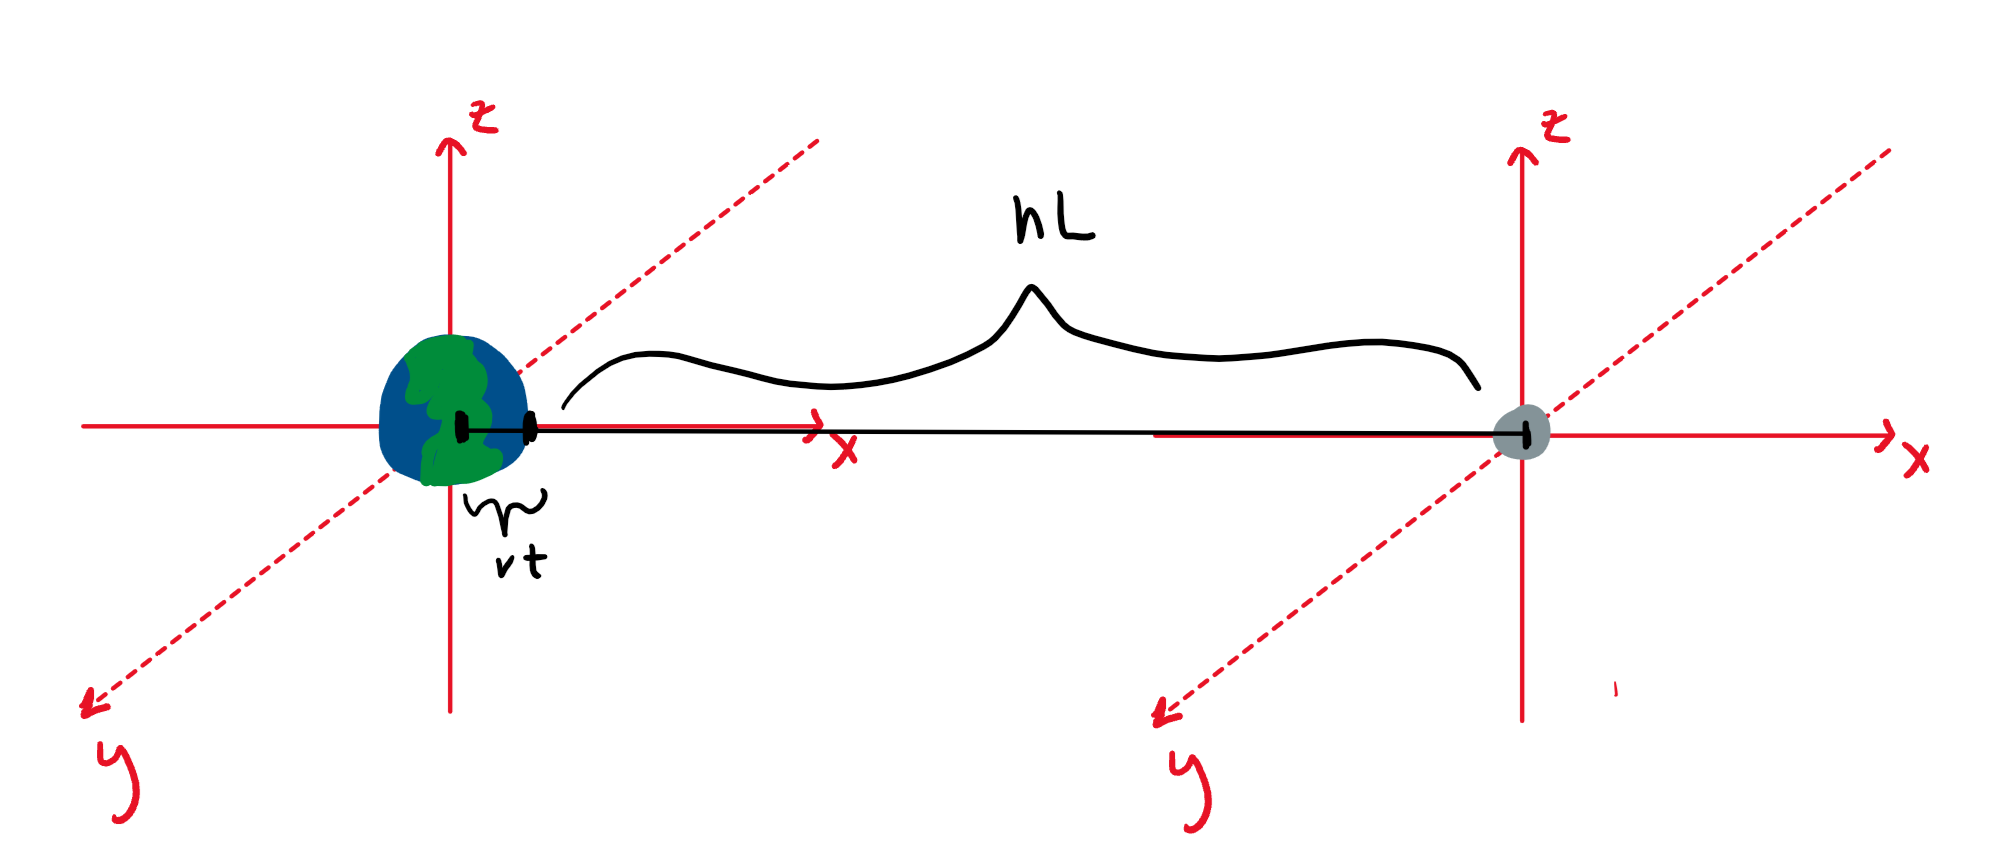


$$y=\left\lbrack \begin{array}{c}
r\\
v
\end{array}\right\rbrack$$



$$\mathrm{y'}=\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack$$


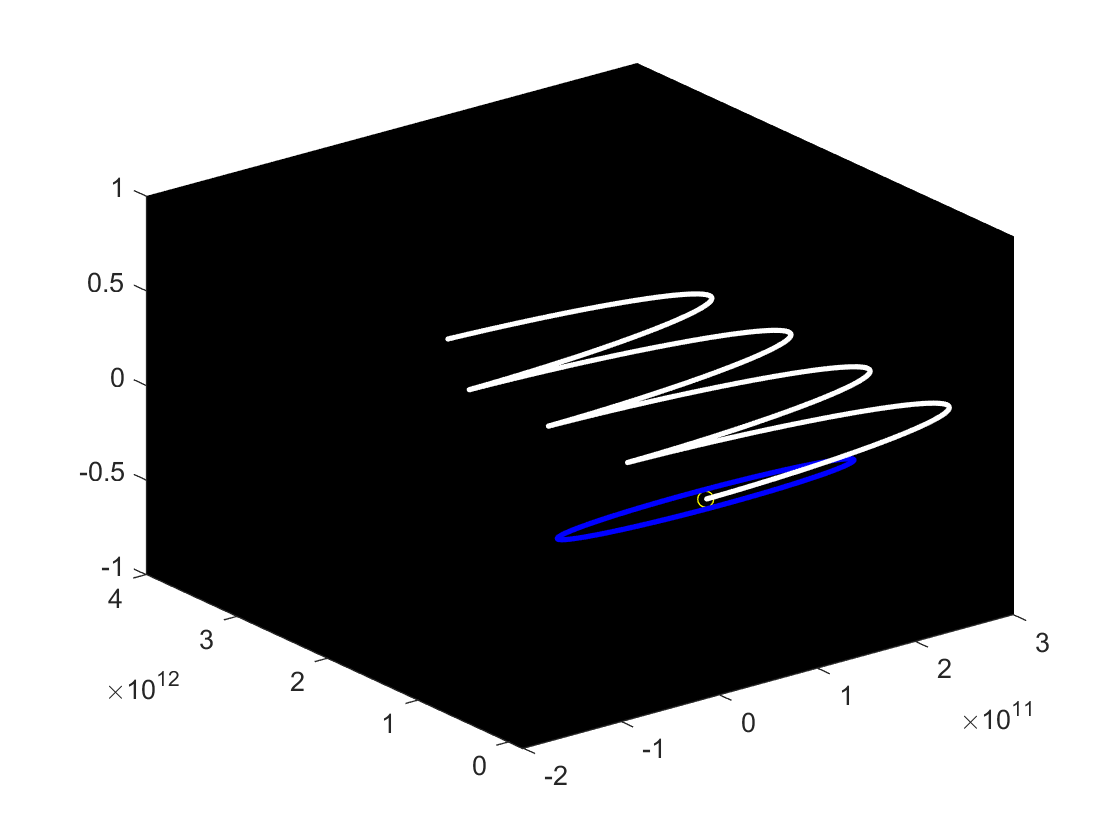

% Un satélite orbitando la Tierra
% La Tierra en el origen (inicialmente)
% El satélite tiene una masa de 20 toneladas 
% y se encuentra a 108 km de altura (eje x)
% Los vectores tienen los datos [Tierra, satélite]
  
% y  = [r;v] 
% y' = [v;a]
% dy/dt = f(t,y)

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mS = 1.989e30;                % masa de Sol
mT = 5.9736e24;               % masa de Tierra
mL = 7.349e22;                % masa de la Luna
m = [mS, mT, mL]; 

rS = 695.510e6;               % radio del Sol m
rT = 6371e3;                        % radio de la Tierra m
hT = 149.6e9;                 % altura de la superficie del Sol a la Tierra
hL = 384400e3;                      % altura de la superficie de la Tierra a la Luna

r0 = [ [0;0;0], [rS+hT;0;0], [rS+rT+hL;0;0] ];      
                                    
vT = sqrt(G * m(1)/r0(1,2));
vL = sqrt(G * m(2)/r0(1,3));  
v0 = [ [0;0;0], [0;vT;0], [0;vL;0] ];         

wT = vT/(rS+hT);
wL = vL/(rS+rT+hL);
 
TT = (2*pi)/wT; 
TL = (2*pi)/wL; 

h = 60000;                 
nv = 10;                 
NkT = nv*ceil(TT/h); 
NkL = nv*ceil(TL/h);

posT = zeros(6,NkT+1);    
posT(:,1) = [r0(:,1);r0(:,2)];
posL = zeros(6,NkL+1);    
posL(:,1) = [r0(:,2);r0(:,3)];

%Esto es un rk4 para la Tierra con respecto al Sol
y1 = [r0(1:end,1:2);v0(1:end,1:2)];
posT = rk4(@f1,NkT, y1, posT, h);

plot3(posT(1,:),posT(2,:),posT(3,:),'oy');
hold on;
plot3(posT(4,:),posT(5,:),posT(6,:),'.b');
grid minor;
hold on;

%Esto es un rk4 para la Luna con respecto a la Tierra
y2 = [r0(:,[2,3]);v0(:,[2,3])];
posL = rk4(@f2, NkL, y2, posL, h);

plot3(posL(4,:),posL(5,:),posL(6,:),'.w');
grid minor;
set(gca,'Color','k')

function ydot = f1(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  dr = r(:,2) - r(:,1);         
  u = dr / norm(dr);            
  dr2 = norm(dr)^2;         	 
  F = (G*m(1)*m(2)/dr2) * u;    
  a = [F/m(1), - F/m(2)];       
  ydot = [v;a];
end

function ydot = f2(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  dr = r(:,2) - r(:,1);         
  u = dr / norm(dr);            
  dr2 = norm(dr)^2;         	 
  F = (G*m(1)*m(3)/dr2) * u;    
  a = [F/m(1), - F/m(3)];       
  ydot = [v;a];
end

function pos = rk4(f, Nk, y, pos, h)
    for t=2:Nk+1
      s1 = f(t,y);
      s2 = f(t+h/2,y+(h/2)*s1);
      s3 = f(t+h/2,y+(h/2)*s2);
      s4 = f(t+h, y+h*s3);
      slope = (s1+2*s2+2*s3+s4)/6;
      y = y + slope*h;
    
      r = y(1:3,:); 
      pos(:,t) = [r(:,1);r(:,2)];  
    end
end